Test THDFFT_V2 for calculating the phase angles between two artificial data sets.

% fs = 50000; %50000; % Sampling frequency (samples per second) 
% delta_t = 1/fs; % seconds per sample 
% StopTime = 10; % seconds 
% t = (0:delta_t:StopTime)'; % seconds 
% F = 60; % Sine wave frequency (hertz) 
% data = cos(2*pi*F*t);
% figure
% scatter(t,data, '.')
% 
% xlabel('time (s)');
% ylabel('Amplitude');
% 
% zeroData = zeros(1,length(t));
% hold on
% scatter(t, zeroData,'.', 'r')
% legend('60 Hz cos(t), sampled at fs', 'Zero Crossing')
% hold off


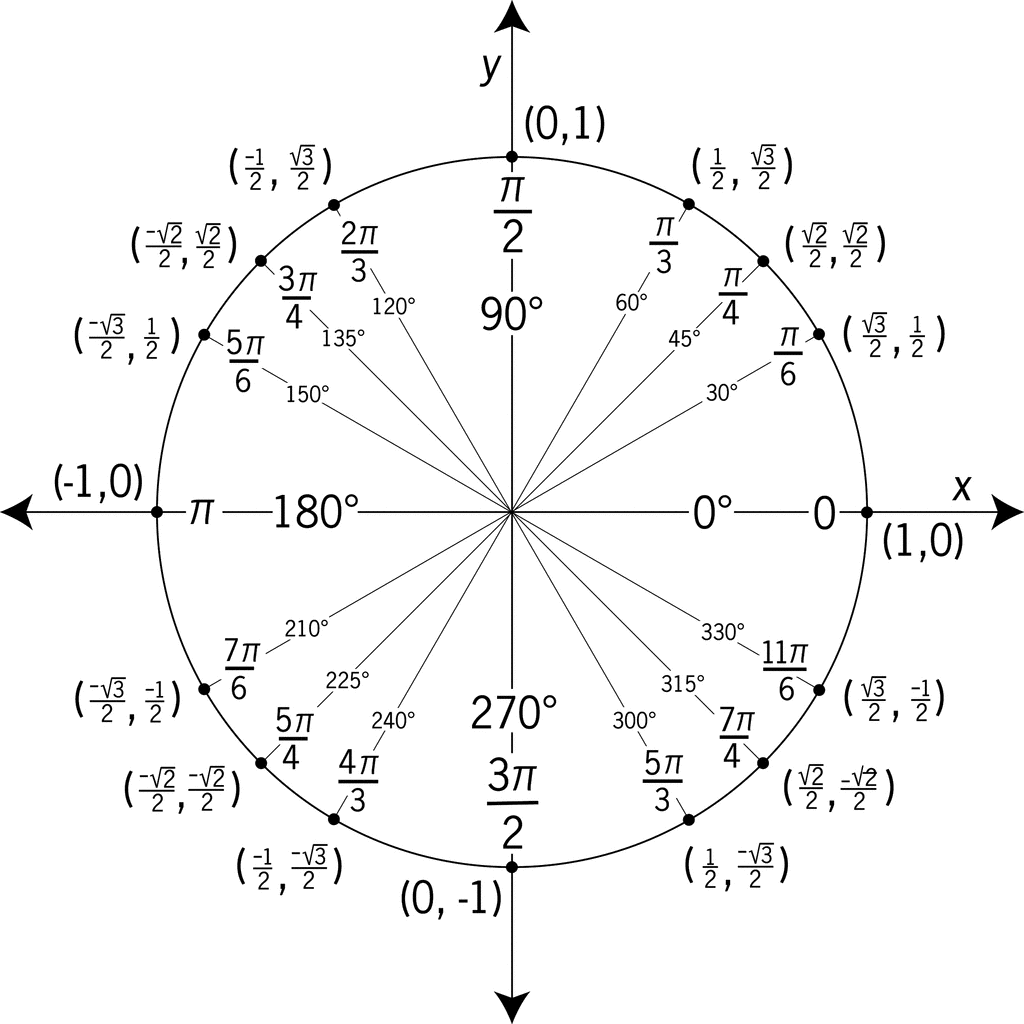

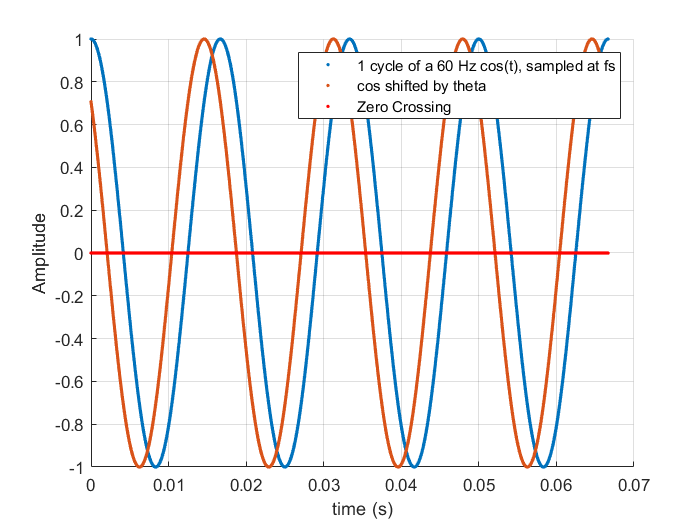

% Get the time of one cycle based on the frequency. For a 60 Hz signal, the
% time for one cycle is 16.7 ms or 0.016 s.

fs = 50000; %50000; % Sampling frequency (samples per second) 
delta_t = 1/fs; % seconds per sample 
F = 60; % Sine wave frequency in hertz 
T = 1/F; % Period 

% time steps for one cycle (time period) 
tt = 0:delta_t:4*T;
Voltage = cos(2*pi*F*tt); % No Phase shift
theta_rad = 7*pi/4; % Phase shift by theta in (rad)
Current = cos(2*pi*F*tt - theta_rad);
figure
scatter(tt,Voltage, '.')
hold on;
scatter(tt,Current, '.')
xlabel('time (s)');
ylabel('Amplitude');
zeroDatatt = zeros(1,length(tt));
hold on
scatter(tt, zeroDatatt,'.', 'r')
legend('1 cycle of a 60 Hz cos(t), sampled at fs', 'cos shifted by theta','Zero Crossing')
grid on
hold off


% =============================================================================
% Correct way of calculating the phase angle difference using fft.  Consider:
% Voltage = cos(2*pi*F*tt); % No Phase shift, and Current = cos(2*pi*F*tt - theta_rad); % with phase shift of theta = pi/4.
% The phase angle (ph_rad/deg) > 0, the current is lagging the voltage.
% Consider: Voltage = cos(2*pi*F*tt); % No Phase shift, and Current = cos(2*pi*F*tt + theta_rad) % with phase shift of theta = pi/4.
% The phase angle (ph_rad/deg) < 0, the current is leading the voltage.   
fft_y1 = fft(Voltage);
fft_y2 = fft(Current);
n = length(Voltage);
halffft_voltage = fft_y1(1:fix(n/2));
halffft_current = fft_y2(1:fix(n/2));
% theta = angle(z) returns the phase angle in the interval [-π,π] for each element of a complex array z. 
% The angles in theta are such that z = abs(z).*exp(i*theta).
ph_rad = angle(halffft_voltage/halffft_current)

ph_rad = -0.7853

ph_deg = rad2deg(ph_rad)

ph_deg = -44.9942


[TV, PV, AV, PdBV, HFV, CompV] = THDFFT(Voltage, fs, F, 1);
[TC, PC, AC, PdBC, HFC, CompC] = THDFFT(Current, fs, F, 1);

nPhase = rad2deg(angle(CompV/CompC))

nPhase = -44.9943


inputs.data = Voltage;
inputs.fs = fs;
inputs.Ff = F;
inputs.harmonic_order = 2;
outputs_V = THDFFT_V2(inputs);

inputs = [];
inputs.data = Current;
inputs.fs = fs;
inputs.Ff = F;
inputs.harmonic_order = 2;
outputs_A = THDFFT_V2(inputs);

% Calculate the phase angel between Voltage and Current
nPhase_THDFFT_V2 = rad2deg(angle((outputs_V.fundamental_freq_complex_coefficients) / (outputs_A.fundamental_freq_complex_coefficients)))

nPhase_THDFFT_V2 = -44.9943


% ===============================================================================

% Calculating the magnitude of phase difference between two sinusoidal functions. The second
% function is phase shifted by theta.
% This calcualtion fails with signals that are non-sinusiodal or noisey.
% Plus, I will need to find a way to check leading and lagging.
theta_radCos = acos(dot(Voltage,Current)/(norm(Voltage)*norm(Current)))

theta_radCos = 0.7853

theta_degCos=theta_radCos*(180/pi)

theta_degCos = 44.9943

% Generating a continuous signal
fs_p = 1024; %50000; % Sampling frequency (samples per second) 
delta_t_p = 1/fs_p; % seconds per sample 
F_p = 16; % 16 Hz
T_p = 1/F_p; % Period 
t_p = -4*T_p:delta_t_p:4*T_p;
x = 2*pi*F_p*t_p;
figure
plot(sin(x), 'r'); hold on
p = 2*sin(x)./x; 
plot(p, 'blue')
xlim([0,513])
legend('sin(x)', 'DTFT - sin(x)/x'); hold off

figure

t_p1 = 0:delta_t_p:4*T_p;
x1 = 2*pi*F_p*t_p1;
freq = 0:fs_p/length(x1):fs_p/2; % frequency in Hz
p1 = 2*sin(x1)./x1;
plot(p1, 'blue')

% ----------------- voltage -------------------------------
voltage_signal = 2*sin(x1); % amplitude of 2 volts

% Two-sided fft
f_p1 = fft(voltage_signal);


hold on
y_p = x1(rem(x1,deg2rad(F_p)) == 0);
ind_p = find(y_p);
fft_p1 = abs(f_p1)./length(x1);

% % % plot(2*abs(f_p1)./length(x1), '--')
plot(2*abs(f_p1(1:floor(length(f_p1)/2+1)))./length(x1), '--')
%xlim([0, 513])
legend('DTFT (sin(x1)/x1)', 'fft of sin(x1)')
figure

% ------------------------------------------------------------------------------------------------------------------------
% In a two-sided spectrum, half the energy is displayed at the positive frequency, and half the energy is displayed at the
% negative frequency. Therefore, to convert from a two-sided spectrum to a single-sided spectrum, discard the second
% half of the array and multiply every point except for DC by two.
% Source: The Fundamentals of FFT-Based Signal Analysis and Measurement
% Michael Cerna and Audrey F. Harvey
l = length(f_p1)/2+1;
fhat = fft_p1(1:floor(l));
fhat(2:end) = 2*fhat(2:end);
% ------------------------------------------------------------------------------------------------------------------------

fhat_t = t_p1(1:floor(l));
normalize_XXdb = 20*log10(abs(fhat)/max(abs(fhat)));

% The amplitude of the original signal (voltage_signal) is represented on the vertical axis. 
stem(freq, fhat)
xticks(freq(1):1:freq(end))
xlim([10, 20])
title('The result is correct b/c we have a exact 16 Hz sin(x)')
ylabel('Amplitude [Volts]')
legend('fft of a 16 Hz Signal')
xlabel('Frequency (Hz)')
% ----------------------------------------------------------------------------------------------------------------------

% Generate a test data
fs_p = 1024;
delta_t_test = 1/fs_p; % seconds per sample 
F_test = 17.5; % 16 Hz fundamental frequency 
T_test = 1/F_test; % Period 
t_test = 0:delta_t_test:4*T_test;
x_test = 2*pi*F_test*t_test;
freq_test = 0:fs_p/length(x_test):fs_p/2; % frequency in Hz
figure
fictitious_continous_signal = 2*sin(x_test);
plot(t_test, fictitious_continous_signal, 'color', 'r', 'Marker', '.')
xlabel('time')
ylabel('Sin(x) [Volts]')
legend('fictitious continous signal')

% Let's take a sample of this continous signal at random rectangular
% window
sample_end = (2^7);
sample_start = 1;

sample = fictitious_continous_signal(sample_start: sample_end);

figure
plot(t_test(sample_start:sample_end), sample, 'color','r', 'Marker',".")
xlabel('time')
ylabel('Sin(x) [Volts]')
legend('Sample of Fictitious Signal', 'Location', 'southwest')

% Run fft on sample data
f_test = fft(sample);
% half of fft
l_test = length(f_test)/2+1;
fhat_test = f_test(1:floor(l_test));
freq_sample = 0:fs_p/length(sample):fs_p/2; % frequency in Hz    
fhat_test(2:end) = 2*fhat_test(2:end); % remove dc component and multiply amplitudes by 2
fft_test = abs(fhat_test)./length(sample);
figure
st = stem(freq_sample, fft_test, 'r', '--');
%xlim([0, 513])
title('Incorrect Amplitude and Frequency Due to Spectral Leakage')
legend('fft of sample')
ylabel('Amplitude (Volts)')
xlabel('Frequency (Hz)')
[sample_amplitude, sample_frequncy_index] = max(fft_test);
dt = datatip(st, 'DataIndex', sample_frequncy_index);
text(100,1, {'Correct Frequency: 17.5 Hz, Correct Amplitude: 2 V', ...
    'Energy is leaking to adjacent frequency bins', ...
    'Since frequency does not fall exactly on the frequency line,' ...
    'the amplitudes seem to be lower.' ...
    'This is called the "picket fence" effect.'})

[THD_fft_C_L1, Percent_THD_fft_C_L1, amplitude_rms_C_L1, powerdB_C_L1, harmf_C_L1] = THDFFT(sample, fs_p, F_test, 1);

% Perform fft on sample data but with zero padding. Zero padding increases
% the fft frequency resolution. 
lpad = 2048-length(sample);
new_sample = [sample, zeros(1,lpad)]
figure
plot(new_sample)
% Run fft on sample data
f_test_pad = fft(new_sample);

% half of fft
l_test_pad = length(f_test_pad)/2+1;
fhat_test_pad = f_test_pad(1:floor(l_test_pad));

freq_sample_pad = 0:fs_p/length(new_sample):fs_p/2; % frequency in Hz    

fhat_test_pad(2:end) = 2*fhat_test_pad(2:end); % remove dc component and multiply amplitudes by 2
fft_test_pad = abs(fhat_test_pad)./length(new_sample);
figure
st_pad = stem(freq_sample_pad, fft_test_pad, 'r', '--');
legend('fft of sample padded with zeros')
ylabel('Amplitude (Volts)')
xlabel('Frequency (Hz)')
[sample_amplitude_pad, sample_frequncy_index_pad] = max(abs(fhat_test_pad));
dt_pad = datatip(st_pad, 'DataIndex', sample_frequncy_index_pad);
approximate_amplitude = sample_amplitude_pad/length(sample);
approximate_frequency = freq_sample_pad(sample_frequncy_index_pad);
str_pad = sprintf('Approximate Amplitude: %.2f [V]\nAppproximate Frequency: %.2f [Hz]',approximate_amplitude, approximate_frequency);
text(200, 0.01, {str_pad})


% Let's see how Windowing works

kaiser_window_sample = kaiser(length(sample), 38); 

sample_kaiser_window = sample .* kaiser_window_sample';
figure
% plot sample data with and without windowing
plot(t_test(sample_start:sample_end), sample, 'color','r', 'Marker',"."); hold on
plot(t_test(sample_start:sample_end), sample_kaiser_window, 'color','blue', 'Marker',"."); hold off

% get the fft of windowed sample data
fft_sample_Kaiser_window = fft(sample_kaiser_window);
% half of fft
l_sample = length(fft_sample_Kaiser_window)/2+1;
fhat_samplekiaser = fft_sample_Kaiser_window(1:floor(l_test));
freq_sample = 0:fs_p/length(sample):fs_p/2; % frequency in Hz    
fhat_samplekiaser(2:end) = 2*fhat_samplekiaser(2:end); % remove dc component and multiply amplitudes by 2
fhat_sample_kiaserWin = abs(fhat_samplekiaser)./length(sample);
figure
st_sample_kaiser = stem(freq_sample, fhat_sample_kiaserWin, 'blue', '--');
[sample_amplitude_kaiser, sample_frequncy_index_kaiser] = max(fhat_sample_kiaserWin);
dt_sample_kiaswer = datatip(st_sample_kaiser, 'DataIndex', sample_frequncy_index_kaiser);

zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);
zx = zci(sample);                                                            % Approximate Zero-Crossing Indices
figure
plot(t_test(sample_start:sample_end), sample, '-b')
hold on
a = t_test(sample_start:sample_end);
plot(a(zx), sample(zx), 'rp')
hold off
grid
legend('Signal', 'Approximate Zero-Crossings')


zeroCrossingsV = zci(Voltage);
zeroCrossingsV_time = tt(zeroCrossingsV);
halfPeriod_V = zeroCrossingsV_time(2) - zeroCrossingsV_time(1);
fullPeriof_V = halfPeriod_V * 2;
scale_factor = pi/halfPeriod_V;
ph_V = scale_factor * (halfPeriod_V) * (180/pi);

zeroCrossingsC = zci(Current);
zeroCrossingsC_time = tt(zeroCrossingsC);
halfPeriod_C =  zeroCrossingsC_time(1) - zeroCrossingsC_time(2) ;

phase_diff_V_C_rad = scale_factor * (zeroCrossingsC_time(1) - zeroCrossingsV_time(1));
phase_diff_V_C_deg = round(phase_diff_V_C_rad * (180/pi))


% Uisng corss-correlation

% % [c, lag] = xcorr(Voltage, Current);
% % [maxC, I] = max(c);
% % 
% % plot(c)
% % PH = (lag(I) * delta_t) * 2 * pi

% % fr = 20; % input signal freq
% % timeStep = 1e-4;
% % t = 0:timeStep:50; % time vector
% % y1 = sin(2*pi*t); % reference signal
% % ph = 0.5; % phase difference to be detected in radians
% % y2 = 0.9 * sin(2*pi*t + ph); % signal, the phase of which, is to be measured relative to the reference signal
% % 
% % [c,lag]=xcorr(y1,y2); % calc. cross-corel-n
% % [maxC,I]=max(c); % find max
% % PH = (lag(I) * timeStep) * 2 * pi; % calculated phase in radians


% To detect leading and lagging (Voltage is the reference signal in
% this case, but it could be any signal that is in the numerator.)

% If z < 0 (has a negtaive slope), then Voltage is leading the current signal by theta.
% If z > 0 (has a positive slope), then the voltage is lagging the current signal by theta

% I am assuming that z is the tan(theta), the angle between the voltage and
% current. In other words, tan(theta) = sin(theta)/cos(theta), where sin(theta) is y-value,
% and cos(theta) is x-value; therefore, z = tan(theta) is the slope, consider a unit circle.
z = Voltage ./ Current;

% Note: atan(z)  = ?, means What angles give me the slopes of z values?
angle_of_z = atan(z);

figure
yyaxis left
plot(Voltage, 'b'); hold on
plot(Current, 'r', 'LineStyle', '-'); 

yyaxis right
plot(angle_of_z, 'g');

% diff Difference and approximate derivative.
% diff(X), for a vector X, is [X(2)-X(1)  X(3)-X(2) ... X(n)-X(n-1)].
% To detect discontinuities 
derivatives_of_z = diff(angle_of_z);
plot(derivatives_of_z, 'Color', 'black'); 
grid on
legend('Voltage', 'Current', 'atan(Voltage/Current)', 'Difference'); hold off
% ingnore the discontinuities


% Good for finding zero crossings
% % t = [1:0.01:5];                                                         % Time Vector
% % y = sin(2*pi*t);                                                        % Signal
% % % zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                    % Returns Zero-Crossing Indices Of Argument Vector
zx = zci(Voltage);                                                            % Approximate Zero-Crossing Indices
figure(1)
plot(tt, Voltage, '-b')
hold on
plot(tt(zx), Voltage(zx), 'rp')
hold off
grid
legend('Signal', 'Approximate Zero-Crossings')


% Doesn't work
[v1, ind] = max(Voltage);
v1_indt = tt(ind)

[v2, ind2] = max(Current);
v2_indt = tt(ind2)
xcros = xcorr(Voltage,Current);
figure
plot(xcros)
phaseSign = v1_indt - v2_indt % the second signal is delayed by this much

if(phaseSign < 0)
    fprintf('If phaseSign < 0, then reference signal is leading by : %.2f deg', theta_degCos)
else
    fprintf('If phaseSign > 0, then reference signal is lagging by: %.2f deg', theta_degCos)
end

x = 0:1e-6:60e-3; % bis 60 ms mit 1µs Schritte 
a = sin(2*pi*F*x);
b = sin(2*pi*F*x - pi);
figure
plot(x,a,x,b)
xlabel(['Winkel in degree ist: ',num2str(theta_degCos)],'Color','r')
y_rad=acos(dot(a,b)/(norm(a)*norm(b)))
y_deg=y_rad*360/(2*pi)
grid on
